# Repaso para examen final

## Problema del bungee jumper (caida libre)

A bungee jumper with a** mass** of 68.1 kg leaps from a stationary hot air balloon. Use

 
$$v\left(t\right)=\sqrt{\frac{\mathrm{gm}}{c_d }\mathrm{tanh}\left(\sqrt{\frac{gc_d }{m}}t\right)}$$
 

to compute velocity for the first 12s of free fall. Also determine the terminal velocity that will be attained for an infinitely long cord (or alternatively, the jumpmaster is having a particularly bad day!). Use a drag coefficient of 0.25 kg/m.

g = 9.81;    % m/s^2
m = 68.1;    % kg
cd = 0.25;   % kg/m
tf=12;  %s
h = 1;
[t,v]= calculoVelocidad(0,tf,h,m,cd,g)

t =      0     1     2     3     4     5     6     7     8     9    10    11    12


v =                    0   9.810000000000000  19.266710352422908  27.713985947855505  34.704364005425504  40.092951079503798  44.001905828903631  46.704094828258611  48.506486628086172  49.678897622944092  50.428718221215163  50.902978054421041  51.200815151304781


% t = 0:h:tf % vector de 1 renglon y varias columnas
% size(t);
% v = zeros(size(t)) %vector con puros ceros
% for i=1:1:length(v)-1
%     %v(i+1) = v(i) + f(v(i))*h
%     v(i+1) = v(i) + (g-(cd/m)*v(i)^2)*h;
% end
plot(t,v);  

title('Bungee Jumper');
xlabel('t, s');
ylabel('v, m/s');
grid on;
hold on; %para que 2 gráficas aparezcan
velocidadTerminal = sqrt(g*m/cd); %me da la amplitud
cte = sqrt(cd*g/m); 
limite=velocidadTerminal*ones(size(t));
plot(t,limite);
legend('exacta', 'aproximada', 'velocidad terminal');

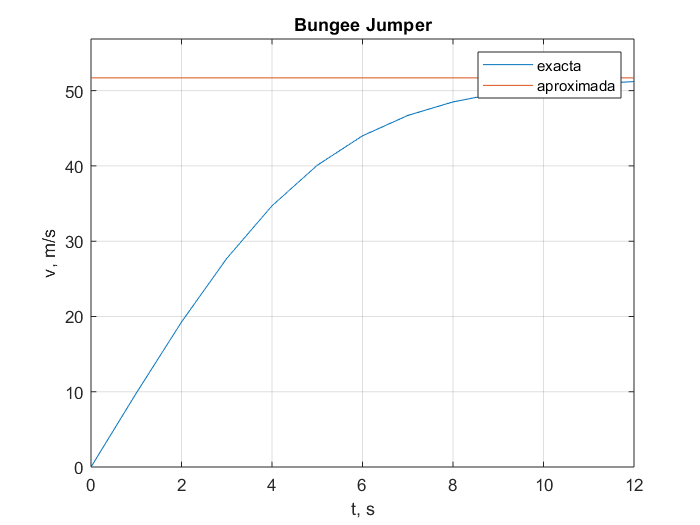

axis([0 tf 0 velocidadTerminal*1.1]);

## Formato IEEE 754. Punto flotante de doble precisión.

Explica a detalle la representación hexadecimal del número -8.75  en el  formato IEEE 754: $x=\mathrm{signo}\;\left(1+f\right)2^e$. En el siguiente código inserta tus observaciones y cálculos para determinar: *signo*, *e*, *f *y *x*. 

num = -8.75;
format hex
repHex = num2hex(num) 

repHex = 'c021800000000000'

format;
% signo = tomamos las primeras 3 cifras de la representación hexadecimal y
% la convertimos a binario en este caso es : 
% c02 que en binario = 1100 0000 0010, vemos si el ultimo bit es 1 entonces
% el signo será negativo.
aux = repHex(1:3)

aux = 'c02'

bin = hexToBinaryVector(aux,12)

bin = 1×12 logical array
   1   1   0   0   0   0   0   0   0   0   1   0


% e = para el exponente debemos utilizar las 11 cifras restantes del 1100 0000 0010
% convertirlo a decimal y a esas 11 cifras restarle 1023.
auxbin = bin(2:end)

auxbin = 1×11 logical array
   1   0   0   0   0   0   0   0   0   1   0


str_b = num2str(auxbin)

str_b = '1  0  0  0  0  0  0  0  0  1  0'

 dec = bin2dec(str_b) 

dec = 1026

 exp = dec - 1023

exp = 3

% f = para obtener la mantissa se debe multiplicar las cifras restantes del
% numero a convertir por 16 elevado a la potencia negativa de su posición
% comenzando de izquierda a derecha 
aux2 = repHex(4:end);
bin2 = hexToBinaryVector(aux2,52); % se obtiene el número en un vector de 52 bits.  
i=-1;
j=1;
a = 1;
b = 4;
suma = 0;
aux = bin2;
% A continuación se convertirá cada digito de la cadena en hexadecimal a
% binario y posteriormente multiplicarlo por 16 elevado al exponente que le
% corresponde
while (j < 13) 
    aux2 = aux(a:b);
    str = num2str(aux2); % Convertir un vector binario en string
    aux3 = bin2dec(str); % string binario a decimal
    aux4 = aux3*(16^i); 
    suma = suma + aux4;
    a=a+4;
    b=b+4;
    j=j+1;
    i = i-1;
end
suma

suma = 0.0938

% x = se utiliza la formula x = -(1+f)*2^e
num = -(suma + 1)*(2^exp)

num = -8.7500

## Modelado de sistemas físicos. Movimiento en caída libre con aceleración constante. 

En Acapulco, clavadistas saltan al mar desde un risco (Ohanian & Markert, "Física para ingeniería y ciencias"). 

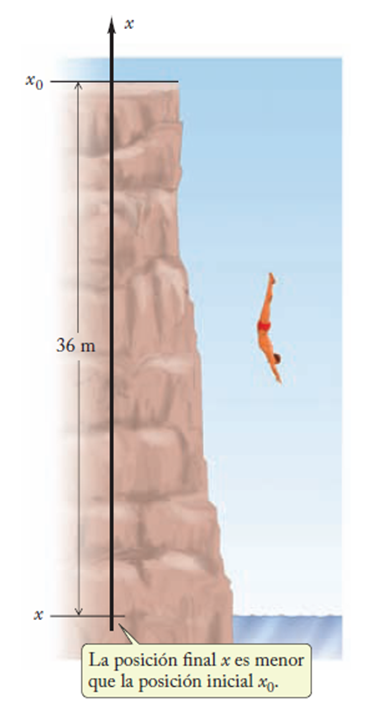

Sabiendo que $\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x$$=-g$ y que $x\left(0\right)=x_0$, $v\left(0\right)=v_o$, obtén las ecuaciones que modelan la posición *x* y la velocidad *v* de los cavadistas. 

% a = g 
% la 2da derivada era la ecuación y las siguientes son las 2 condiciones iniciales.
%x = desplazamiento
%x' = velocidad
%x''= aceleración
syms x(t) V(t) g x0 v0
eqn = diff(x,t,2) == -g

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-g$$

Dx = diff(x,t,1)

$$Dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

cond = [x(0)==x0, Dx(0)==v0]

$$cond = \left(\begin{array}{cc} x\left(0\right)=x_{0} & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=v_{0} \end{array}\right)$$

xSol(t) = dsolve(eqn,cond)

$$xSol(t) = -\frac{g\,t^{2}}{2}+v_{0}\,t+x_{0}$$

vP = diff(xSol,t)

$$vP(t) = v_{0}-g\,t$$

Suponiendo que la velocidad inicial es cero, que los clavadistas caen desde una altura de 36m y que g=9.81m/s, aplica las ecuaciones encontradas para determinar ¿durante cuánto tiempo caen? ¿A qué velocidad entran al agua?

v0 =0;
x0=36;
g = 9.81;

xS = subs(xSol) % subs es symbolic substitution

$$xS(t) = 36-\frac{981\,t^{2}}{200}$$

vS = subs(vP)

$$vS(t) = -\frac{981\,t}{100}$$


xF = matlabFunction(xS); % convierte una funcion simbolica a una funcion anonima
vF = matlabFunction(vS);
fplot(xF,[0,5]);
hold on;
fplot(vF,[0,5]);
legend('x', 'v');
grid on;
hold off;
[t,i] = newtonRaphson(xF,2,3) %

t = 2.7091

i = 5

v = vF(t);

%Cuando llega al mar x=0 entonces cae durante :
t = sqrt(2*x0/g);
% llega a una velocidad de:
v = v0-g*t;

## Raíces de una ecuación

**Newton rhapson **es un método para resolver ecuaciones no lineales y encontrar raices sabiendo su derivada.

Encuentra las tres raíces del polinomio:


$$p\left(x\right)=x^3 -15x-4$$


Primero grafica la función en el intervalo [-4,5] para ver la localización aproximada (o exacta) de las raíces. Después usa el algoritmo de Newton-Raphson (cuyo código se encuentra al final de este script) para encontrar las raíces.

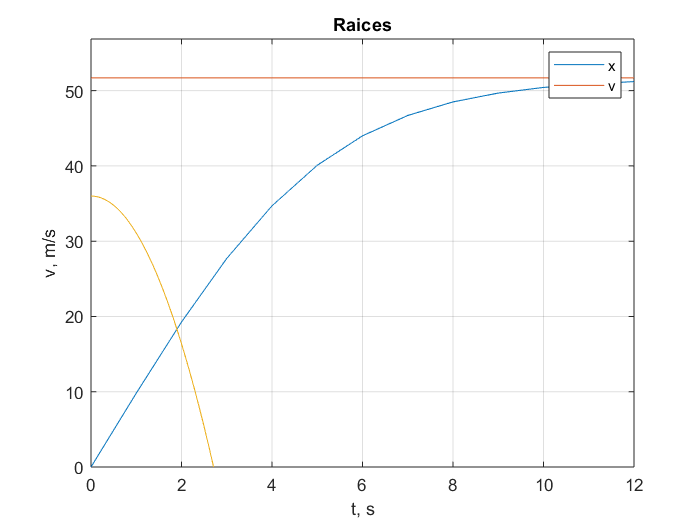

p = @(x) x.^3-15*x - 4;
a = -4; b = 5;
title('Raices');

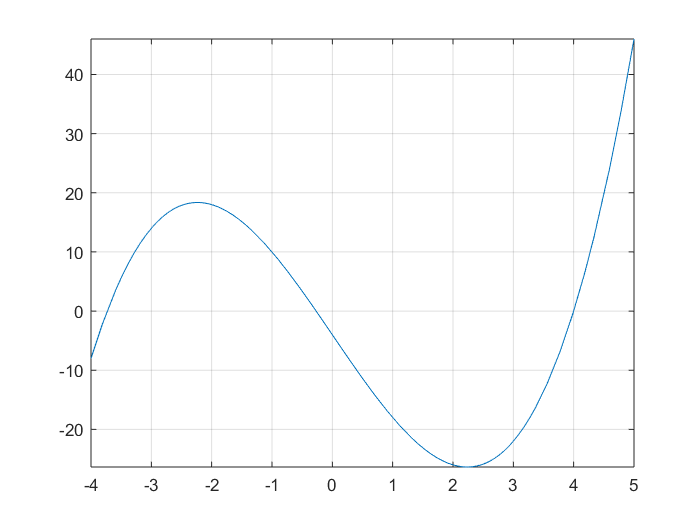

fplot(p,[a,b]);
grid on;

disp("Primer raíz")

Primer raíz


[x,~] = newtonRaphson(p,-4,-3)

x = -3.7321

disp("Segunda raíz")

Segunda raíz


[x,~] = newtonRaphson(p,-1,0)

x = -0.2679

disp("Tercer raíz")

Tercer raíz


[x,~] = newtonRaphson(p,3,5)

x = 4

De acuerdo con el principio de Arquímedes, la** fuerza de flotación** es igual al** peso del fluido desplazado** por la porción sumergida de un objeto. Para la esfera de corcho ilustrada en la siguiente figura, usa el método de bisección para determinar la altura h de la porción que queda encima del agua. Utiliza los siguientes valores para tu cálculo:** r = 1m**, densidad de la esfera **ρe = 200kg/m3** y densidad del agua **ρa = 1000kg/m3**. Observa que el volumen de la porción de la esfera por encima del agua se puede calcular mediante:


$$V=\frac{\pi h^2 }{3}\left(3r-h\right)$$


***Para estar en equilibrio***, la fuerza de flotación (que depende de h) ***debe ser igual*** al peso total de la esfera. Recuerda que **F=mg** y** m=ρV**. Por lo tanto, **F = ρVg**. ¿Peso de la  esfera? ¿Volumen sumergido (desplazado)? ¿Fuerza de flotación? `En equilibrio la fuerza total es cero.`

- Escribe la función que especifica la fuerza total.

- Grafica esta función dentro de límites adecuados.

-  Elige valores iniciales para la función de bisección.

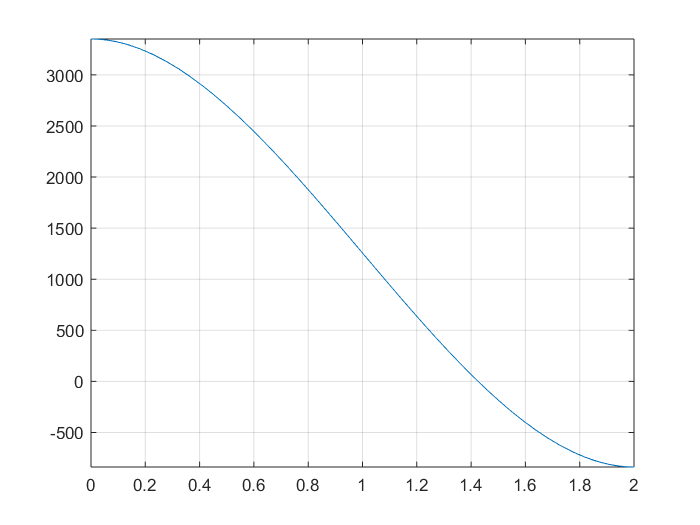

r=1;
pe=200;
pa=1000;
volEsfera = (4/3)*r^3*pi;
%f = volTotal*dif de densidades - volFuera *densidadAgua
ft = @(h) volEsfera*(pa-pe) - pa*((pi*h.^2).*((3*r-h)/3));
a=0;
b=2*r;
fplot(ft,[a,b]);
grid on;

[x,i] = biseccion(ft,1.4,1.6)

x =    1.425718549166519


i =     48


#### Optimización con newton rhapson 

El método de Newton-Raphson permite encontrar la raíz x de una función de tal manera que f(x)=0. Para encontrar un valor óptimo de f(x) puede usarse una función similar recordando que en un punto crítico f’(x)=0. Programa la función [x,i,min] = optNR(f, x0) que encuentra un punto crítico de f iniciando con el valor x0. El valor lógico min regresado debe indicar si el valor crítico se trata de un mínimo (true) o un máximo (false). Prueba tu función con : $f\left(x\right)=2\times \mathrm{Sin}\left(x\right)-\frac{x^2 }{10}$

- Grafica f(x) en el intervalo [0,4] para encontrar un valor adecuado para x0.

- Utiliza tu función de optimización que implementa la proporción aurea para verificar que obtienes el mismo valor.

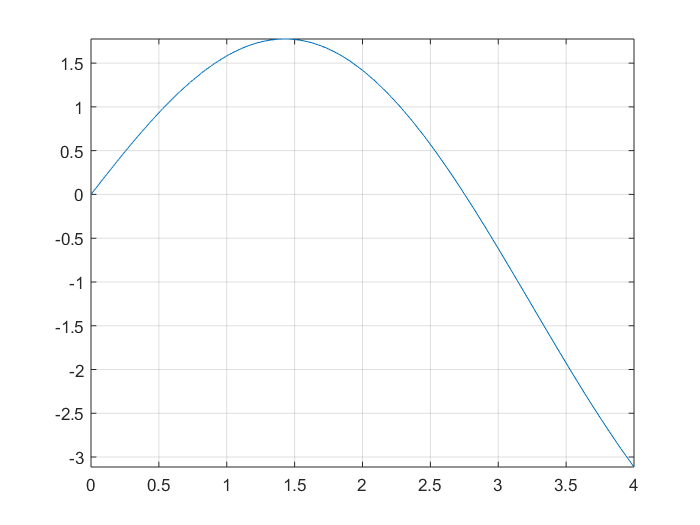

fx = @(x) 2*sin(x) - x.^2/10;
fplot(fx,[0,4])
grid on;

[x,i,min] = newtownRaphsonOptimizacion(fx,0,2)

x =    1.427551778764594


i =      5


min = logical
   0


Utiliza tu algoritmo de Gauss-Seidel (cópialo más abajo) para resolver el sistema Ax = b, donde:


$$A=\left\lbrack \begin{array}{ccc}
0\ldotp 1 & 7 & -0\ldotp 3\\
3 & -0\ldotp 1 & -0\ldotp 2\\
0\ldotp 3 & -0\ldotp 2 & 10
\end{array}\right\rbrack$$



$$b=\left\lbrack \begin{array}{c}
-19\ldotp 3\\
7\ldotp 85\\
71\ldotp 4
\end{array}\right\rbrack$$


Si es necesario, reordena los renglones de A y b usando una matriz de permutación P

A= [0.1 7 -0.3; 3 -0.1 -0.2; 0.3 -0.2 10]

A =    0.100000000000000   7.000000000000000  -0.300000000000000
   3.000000000000000  -0.100000000000000  -0.200000000000000
   0.300000000000000  -0.200000000000000  10.000000000000000


b = [-19.3;7.85;71.4];   
P = [0 1 0 ; 1 0 0 ; 0 0 1]

P =      0     1     0
     1     0     0
     0     0     1


C = P*A % Matriz permutada

C =    3.000000000000000  -0.100000000000000  -0.200000000000000
   0.100000000000000   7.000000000000000  -0.300000000000000
   0.300000000000000  -0.200000000000000  10.000000000000000


d= P*b

d =    7.850000000000000
 -19.300000000000001
  71.400000000000006


[x,i] = GaussSeidel2(C,d)

x =    2.999999998055568
  -2.500000000456044
   7.000000000049214


i =      5


Resuelve el siguiente sistema de ecuaciones usando el método de Newton de varias variables (cópialo más abajo):


$$2x_1 +x_2 +2x_3^2 \;=\;5$$



$$x_2^3 +4x_3 =4$$



$$x_1 x_2 +x_3 -e^{x_3 } =0$$


Considera como valor inicial x=[1;1;0]

%f = @(x) [2*x(1)+x(2)+2*x(3)^2-5;x(2)^3+4*x(3)-4;x(1)*x(2)+x(3)-exp(x(3))];
%j = @(x) [2 1 4*x(3);0 3*x(2)^2 4; x(2) x(1) 1-exp(x(3))];
%x0=[1;1;0];
%[x,i] = NewthonRaphsonVV(f,j,x0)

Resuelve el siguiente problema de valor inicial en el intervalo de t=0 a t=2, donde y(0)=1. Grafica la solución $y\left(t\right)$.


$$\frac{\textrm{d}}{\textrm{d}t}y=yt^2 -1\ldotp 1y$$


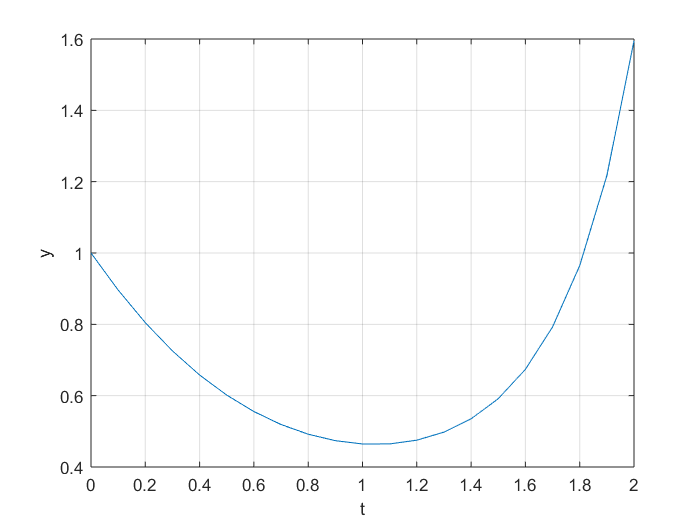

%
y0=1;
f= @(t,y) y*t^2-1.1*y;
h=0.1;
t0=0;
tf=2;
[t,y] = ivps(f,t0,y0,h,tf,'rk4');
plot(t,y)
xlabel('t');
ylabel('y');
grid on;

Calcula la suma del último renglón de la matriz A (de la manera más "elegante" posible)

 A = [1,2,-1;2,1,-2;-3,1,1;1,2,3];
 suma = sum(A(end,:))

suma =      6


 Reemplaza la primera columna de A con ceros. 

A(:,1) = zeros(length(A),1)

A =      0     2    -1
     0     1    -2
     0     1     1
     0     2     3


2.1 La serie infinita


$$f\left(n\right)=\sum_{i=1}^n \frac{1}{i^4 }$$


converge a $\frac{\pi^4 }{90}$ conforme $n$ tiende a infinito. Escribe un programa de precisión sencilla para calcular $f\left(n\right)$ para $n=10000$, calculando la suma desde $i=1$ hasta 10000 y después en sentido inverso En cada caso, calcula el error absoluto. 

real = single(pi^4/90) %precisión simple

real = single
   1.0823232


 suma = single(0);

for i = 1:10000
    suma = suma + 1/i^4;
end

suma

suma = single
   1.0823221



errorAbs = real-suma

errorAbs = single
   1.0728836e-06



%suma inversa

sumaInv = single(0);

for j=10000:-1:1
    sumaInv = sumaInv + 1/j^4;
end

sumaInv

sumaInv = single
   1.0823232


errorAbs = real-sumaInv

errorAbs = single
     0


2.2 Determina el número de términos necesarios para aproximar $\mathrm{cos}\left(0\ldotp 3\pi \right)\;$ a 8 decimales con el uso de la serie de Maclaurin.

$\mathrm{cos}\;x=1-\frac{x^2 }{2!}$+$\frac{x^4 }{4!}$-$\frac{x^6 }{6!}$+$\frac{x^8 }{8!}-\cdots$


cos(0.3*pi)

ans =    0.587785252292473


x=0.3*pi;
coseno =1;
for i=1:10
    coseno= coseno + (-1)^(i)*((x^(2*i))/factorial(2*i));
end
coseno

coseno =    0.587785252292473


3.1 De acuerdo con el principio de Arquímedes, la fuerza de flotación es igual al peso de fluido desplazado por la porción sumergida de un objeto. Para el tronco de un cono, determina la altura $h_1$ de la porción que queda encima del agua. 

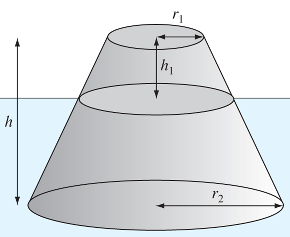

El volumen del tronco está dado por:


$$V=\frac{\pi h}{3}\left({r_1 }^2 +{r_2 }^2 +r_1 r_2 \right)$$


Sea r el radio a la altura de la superficie del agua. Por triángulos semejantes se sabe que:


$$\frac{r-r_1 }{h_1 }=\frac{r_2 -r_1 }{h}$$



$$r=r_1 +\frac{r_2 -r_1 }{h}h_1$$


Usa los siguientes valores para el cálculo;

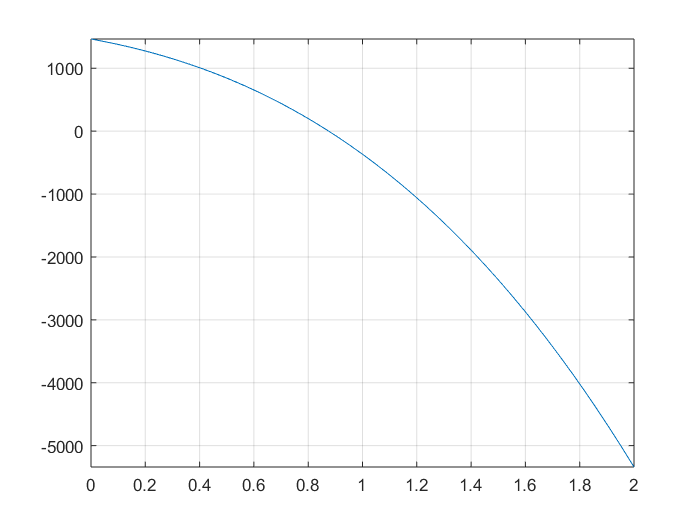

r1 = 0.5;           % m
r2 = 1;
h = 1;
rhoF = 200;         % densidad del cono kg/m^3
rhoA = 1000;        % densidad del agua

volTronco= (((pi*h)/3)*(r1^2+r2^2+r1*r2))*(rhoA-rhoF);
auxRadio = (r2-r1)/h;
f = @(h1) volTronco - (((pi.*h1)/3).*(r1.^2 + (r1 + ((r2-r1)/h).*h1).^2 + r1.*(r1+((r2-r1)/h).*h1)))*rhoA;
int = [0,2*r2];
fplot(f, int);
grid on;


[x,i] = biseccion(f,0.8,1.0)

x =    0.875777455366903


i =     50


 Manejas un coche a una velocidad constante de 40 km/h de A a B. Cuando llegas a B regresas inmediatamente a A pero a una velocidad constante de 60 km/h. ¿Cuál es la velocidad promedio del viaje completo?

v1 = 40;
v2 = 60;
B = 100;
A = 20;
t1 = (B-A)/v1

t1 =      2


t2 = (B-A)/v2

t2 =    1.333333333333333


prom = ((v1*t1)+(v2*t2))/(t1+t2)

prom =   48.000000000000007


Se desea resolver el siguiente sistema de ecuaciones no lineales

 
$$y=x^2 +1$$



$$y=2\;\mathrm{cos}\;x$$


Grafica las ecuaciones ($\left.x>0\right)$ para obtener aproximaciones iniciales para $x$ y $y$:

y = @(x) x.^2 +1

y = function_handle with value:
    @(x)x.^2+1


y1 = @(x) 2*cos(x)

y1 = function_handle with value:
    @(x)2*cos(x)


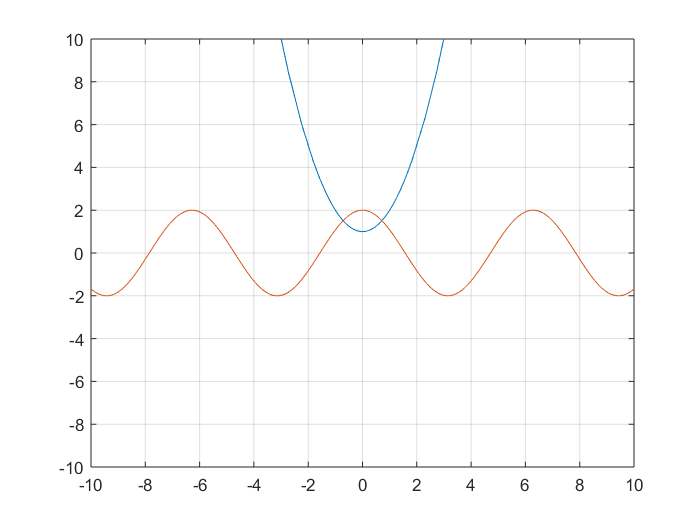

int = [-10,10];
fplot(y,int);
grid on;
hold on;
fplot(y1,int)
ylim([-10 10])

f = @(x) [x(1)^2 + 1 ;
          2*cos(x(1))];

J = @(x) [ 2*x(1);
           -2*sin(x(1))];


%Sacar jacobiano
syms xs1;
xs = xs1;
fs = [xs1^2 - 1 ;
      2*cos(xs1) ];
      
Js = jacobian(fs,xs)

$$Js = \left(\begin{array}{c} 2\,{\mathrm{xs}}_{1}\\ -2\,\sin\left({\mathrm{xs}}_{1}\right) \end{array}\right)$$


x0 = [-2; 2];
[x,i] = NewthonRaphsonVV(f,J,x0)

x =   -0.671436260473540
   3.328563739526461


i =     19


Se lanza un proyectil hacia arriba desde la superficie de la Tierra con una velocidad inicial de 1500 m/s. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza debida a la gravedad hacia abajo. En estas condiciones, se usa un balance de fuerzas para obtener:


$$\frac{\textrm{d}}{\textrm{d}t}v=-g\frac{R^2 }{{\left(R+x\right)}^2 }$$


donde $v$ es la velocidad hacia arriba (m/s) y $x$ es la altitud (m) medida hacia arriba a partir de la superficie terrestre. 

Grafica la altura $x$ del proyectil en los primeros 250s de vuelo.

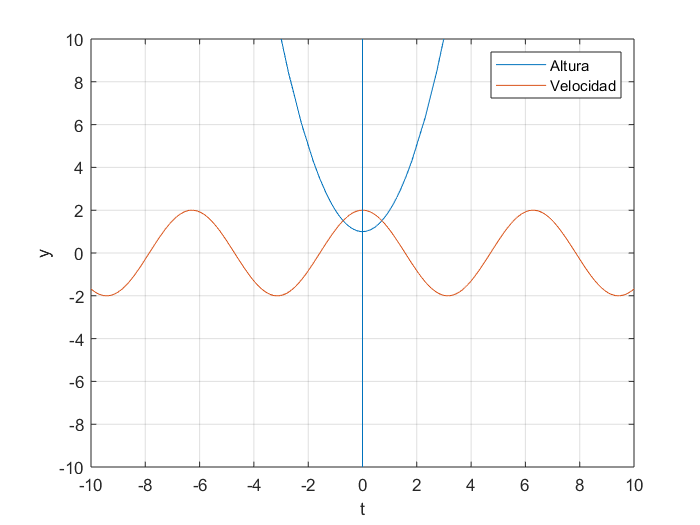

v0=1500;
R = 6.37e6;
g = 9.81;
y0=1500;
f = @(t,y) -g*((R^2)/(R+y^2));
h=0.1;
t0=0;
tf=250;
[t,y] = ivps(f,t0,y0,h,tf,'rk4');
plot(t,y)
xlabel('t');
ylabel('y');
grid minor;
legend('Altura','Velocidad')

alturaMax = abs(y(:,end))

alturaMax =      2.327937053835618e+06
